%%%%%%%%% Step 1: Create mesh %%%%%%%%%
% First, we need to create a mesh of the domain and refine it to capture the observed ice flow velocity. As you have seen in the mesh tutorial, we
% first create a uniform mesh, interpolate the surface velocity and use it as a metric to refine our initial mesh. Most of the code is provided to
% you. You only need to find the observation error so that the mesh has about 5,000 elements . 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Mesh parameters
domain = 'Ross_Ice_shelf.exp' % may be just need to change the domain anywhere in Antarctica

domain = 'Ross_Ice_shelf.exp'

hinit=7000;	% element size for the initial mesh
hmax=12000;		% maximum element size of the final mesh
hmin=5000;		% minimum element size of the final mesh
gradation=1.7;	% maximum size ratio between two neighboring elements
err= 8;			% maximum error between interpolated and control field

% Generate an initial uniform mesh (resolution = hinit m)
cd '/Users/rishi/Desktop/ISSM/examples/Pig'
md=bamg(model,'domain',domain,'hmax',hinit);

At least one contour was not correctly oriented and has been re-oriented
Construction of a mesh from a given geometry


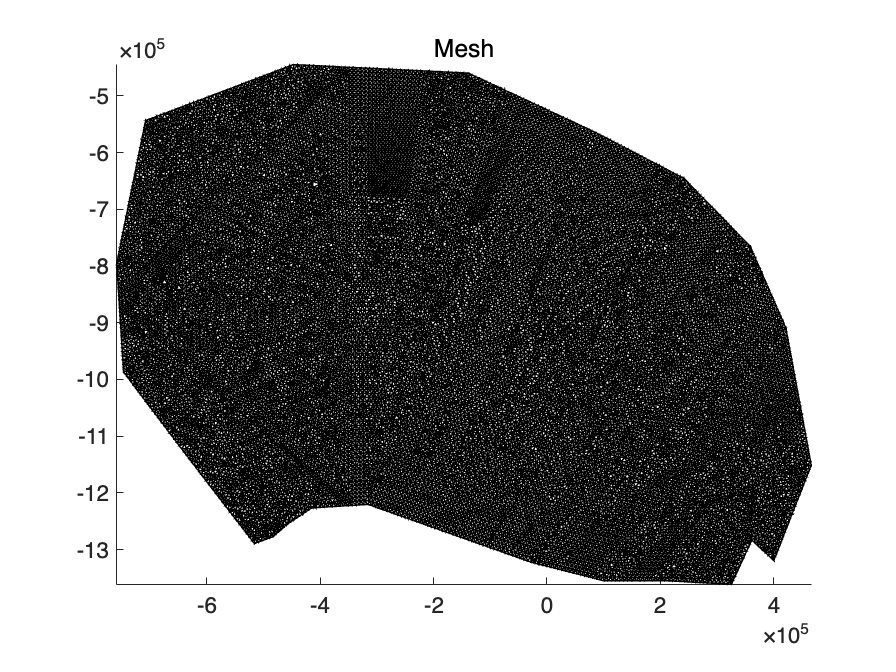

plotmodel(md,'data','mesh')

% Interpolate velocity so that it can be used as a metric
% interpMouginotAnt2019
[vx_obs, vy_obs]= interpMouginotAnt2019 (md.mesh.x,md.mesh.y,...
    '/Users/rishi/Desktop/ISSM/examples/Data/antarctic_ice_vel_phase_map_v01.nc');

   -- Mouginot 2019: loading velocities
   -- Mouginot 2019: interpolating 


vel_obs=sqrt(vx_obs.^2+vy_obs.^2);

% Adapt the mesh to minimize error in velocity interpolation
md=bamg(md,'hmax',hmax,'hmin',hmin,'gradation',gradation,'field',vel_obs,'err',err);

Anisotropic mesh adaptation
   new number of triangles = 16307


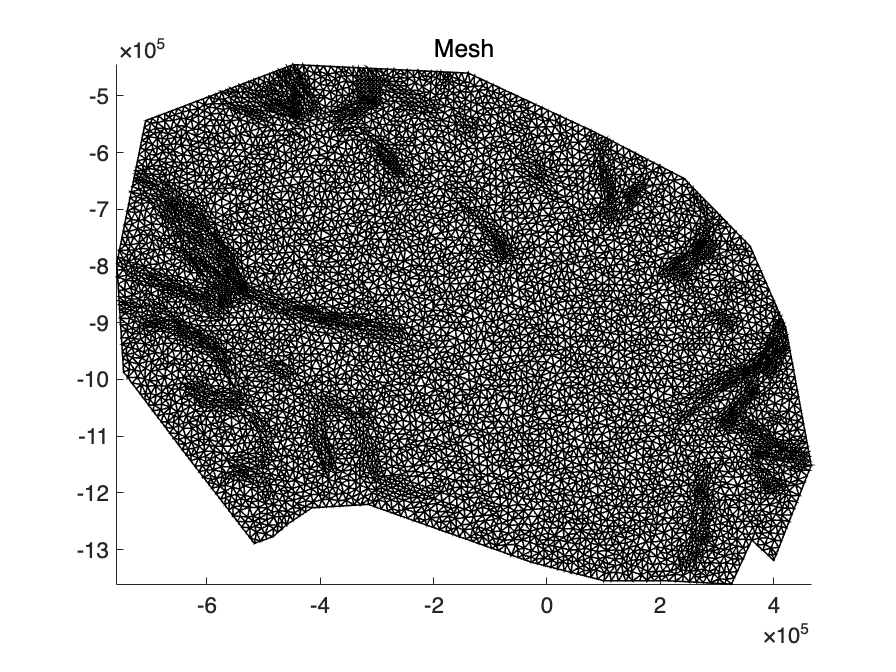

plotmodel(md,'data','mesh')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Step 2: Parameterize model
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% We need to provide all the model parameters to intialize the model including:
% - set the ice mask (using a level-set)
% - interpolate the geometry from BedMachine (bed, surface, base, thickness, grounding line)
% - interpolate observed velocities to prepare the inversion
% - initialize friction parameters and rheology parameters (Budd sliding law )
% - set boundary conditions
% - set flow equation
% - choose a model name
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% Step-2.1 : set the ice mask (using a level-set)
% -----------------------------------------------

% read the msak from the Bedmachine dataset
mask = interpBedmachineAntarctica(md.mesh.x,md.mesh.y,'mask','linear',...
    '/Users/rishi/Desktop/ISSM/examples/Data/BedMachineAntarctica-v3.nc');

   -- BedMachine Antarctica version: /Users/rishi/Desktop/ISSM/examples/Data/BedMachineAntarctica-v3.nc
   -- BedMachine Antarctica: loading mask
   -- BedMachine Antarctica: interpolating mask
       -- Interpolation method: linear



% initialize the mesh of ice mask == same as the number of vertices
md.mask.ice_levelset = ones(md.mesh.numberofvertices,1); 
md.mask.ice_levelset(mask>1.5) = -1;                                  % the ice mask should be >1.5 in bedmachine
md.mask.ice_levelset = reinitializelevelset(md,md.mask.ice_levelset); % reinitialize level set


% Step-2.2: interpolate the geometry from BedMachine (bed, surface, base, thickness, grounding line)
% ------------------------------------------------------------------------------------------------

% Surface and Bed information from BedMachine
md.geometry.surface = interpBedmachineAntarctica(md.mesh.x,md.mesh.y,'surface','linear',...
    '/Users/rishi/Desktop/ISSM/examples/Data/BedMachineAntarctica-v3.nc');

   -- BedMachine Antarctica version: /Users/rishi/Desktop/ISSM/examples/Data/BedMachineAntarctica-v3.nc
   -- BedMachine Antarctica: loading surface
   -- BedMachine Antarctica: interpolating surface
       -- Interpolation method: linear



md.geometry.bed = interpBedmachineAntarctica(md.mesh.x,md.mesh.y,'bed','linear',...
    '/Users/rishi/Desktop/ISSM/examples/Data/BedMachineAntarctica-v3.nc');

   -- BedMachine Antarctica version: /Users/rishi/Desktop/ISSM/examples/Data/BedMachineAntarctica-v3.nc
   -- BedMachine Antarctica: loading bed
   -- BedMachine Antarctica: interpolating bed
       -- Interpolation method: linear



md.geometry.base = md.geometry.bed; % ice-shelf base same as the bed

% calculation for using hydrostatic equilibrium for the ice shelf
rho_water = 1028.9;
di = md.materials.rho_ice/rho_water;
pos = find(-di/(1-di)*md.geometry.surface > md.geometry.bed);
md.geometry.base(pos) = di/(di-1)*md.geometry.surface(pos);
md.geometry.thickness = md.geometry.surface - md.geometry.base;
md.mask.ocean_levelset = md.geometry.thickness+md.geometry.bed/di;


% Step-2.3 : interpolate observed velocities to prepare the inversion
% -----------------------------------------------------------------

% Observed velocity
% interpolate observed velocity from the velocity netcdf file
[md.inversion.vx_obs, md.inversion.vy_obs] = interpMouginotAnt2019 (md.mesh.x,md.mesh.y,...
    '/Users/rishi/Desktop/ISSM/examples/Data/antarctic_ice_vel_phase_map_v01.nc');

   -- Mouginot 2019: loading velocities
   -- Mouginot 2019: interpolating 


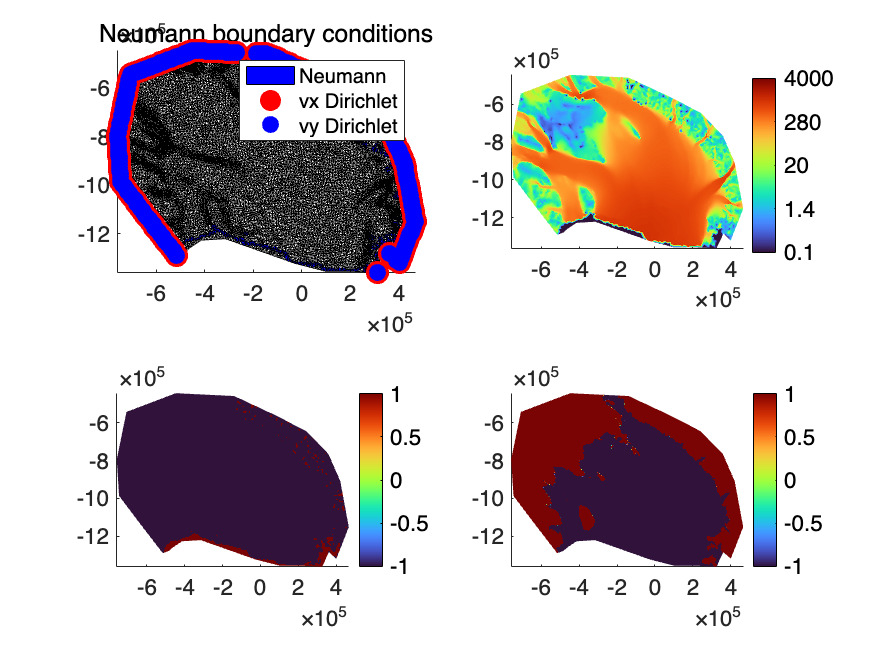


md.inversion.vx_obs(isnan(md.inversion.vx_obs)) = 0; % make all the nan values to be zero
md.inversion.vy_obs(isnan(md.inversion.vy_obs)) = 0;
md.inversion.vel_obs = sqrt(md.inversion.vx_obs.^2 + md.inversion.vy_obs.^2); % compute velocity from vx and vy


% Step-2.4 : initialize friction parameters and rheology parameters
% -----------------------------------------------------------------

% initialize Sliding parameters (uniform 200 by default)
md.friction.coefficient = 200 * ones(md.mesh.numberofvertices, 1);
md.friction.p = ones(md.mesh.numberofelements, 1);
md.friction.q = ones(md.mesh.numberofelements, 1);

% Initialize Rheology parameters, assuming ice is at -10°C
md.materials.rheology_B = cuffey(273.15-10) * ones(md.mesh.numberofvertices, 1);
md.materials.rheology_n = 3 * ones(md.mesh.numberofelements, 1);

% Other parameters (just ignore)
md.stressbalance.referential = NaN(md.mesh.numberofvertices,6);
md.stressbalance.loadingforce = zeros(md.mesh.numberofvertices,3);

% Step-2.5 : Set Boundary conditions
% ----------------------------------

% Set Boundary conditions: constrain inflow velocities only
md.stressbalance.spcvx = NaN(md.mesh.numberofvertices,1);
md.stressbalance.spcvy = NaN(md.mesh.numberofvertices,1);
md.stressbalance.spcvz = NaN(md.mesh.numberofvertices,1);
pos = find(md.mesh.vertexonboundary & md.mask.ocean_levelset>0);
md.stressbalance.spcvx(pos) = md.inversion.vx_obs(pos);
md.stressbalance.spcvy(pos) = md.inversion.vy_obs(pos);

% Step-2.6 : Set flowequation as SSA
% ---------------------------------- 
md = setflowequation(md,'SSA','all');

% Model name
md.miscellaneous.name = 'Ross_Inversion';
save ./Models/Ross_Parameterized md;

% Plot some parameters
plotmodel(md,'data','BC', ... % boundary conditions
    'data',md.inversion.vel_obs,'log#2',10,'caxis#2',[0.1 4000],... % observed velocity 
    'data',md.mask.ice_levelset,'caxis#3',[-1 1], ... % masked ice and no ice
    'data',md.mask.ocean_levelset,'caxis#4',[-1 1]) % masked ice and ocean

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Step 3: Infer ice shelf rheology
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Our initial guess for the ice rheology prefactor (B) needs to be refined in order to match the observed velocities. As you have seen in the
% inversion tutorial, we need to:
% 
% Set-up the inversion parameters
% Extract the ice shelf area so that we only perform the inversion on a small section of the domain
% Invert for B on the ice shelf
% Plot the results
% Update the "bigger" model with the rheology prefactor from the extracted model

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% We are going to use the sum of 3 cost functions:
% 101, which is our regular least squares fit
% 103, the difference in log scale
% 501, Tikhonov regularization, which penalizes strong gradients in B

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% Control general
md.inversion= m1qn3inversion(md.inversion);
md.inversion.iscontrol = 1; % controlled experiments
md.inversion.maxsteps = 80; % maximum steps
md.inversion.maxiter = 80;  % maximum interation
md.inversion.dxmin = 0.1; 
md.inversion.gttol = 1.0e-6;

% Cost functions
md.inversion.cost_functions = [101 103 502];
md.inversion.cost_functions_coefficients= ones(md.mesh.numberofvertices,3);
md.inversion.cost_functions_coefficients(:,1) = 1;
md.inversion.cost_functions_coefficients(:,2) = 0.001;
md.inversion.cost_functions_coefficients(:,3) = 1e-18;
pos=find(md.inversion.vx_obs==0 | md.mask.ice_levelset>0);
md.inversion.cost_functions_coefficients(pos,1:2)=0;

% Controls
md.inversion.control_parameters={'MaterialsRheologyBbar'};
md.inversion.min_parameters = md.materials.rheology_B;
md.inversion.max_parameters = md.materials.rheology_B;
pos = find(md.mask.ocean_levelset<0);
md.inversion.min_parameters(pos) = cuffey(273);
md.inversion.max_parameters(pos) = cuffey(200);

% Solve
md.verbose=verbose('control',true);
md.cluster=generic('name',oshostname,'np',2);
mds = extract(md,md.mask.ocean_levelset<0); % only for the ice shelf

NOTE: using observed velocities to create constraints along new boundary


mds=solve(mds,'Stressbalance'); % solving stress balance only for ice shelf

uploading input file and queuing script
launching solution sequence on remote cluster

Ice-sheet and Sea-level System Model (ISSM) version  4.24
(website: http://issm.jpl.nasa.gov forum: https://issm.ess.uci.edu/forum/)

call computational core:
   Initialize M1QN3 parameters
   Computing initial solution

┌────┬─────────────────┬────────────┬──────────────────────────────┐
│Iter│  Cost function  │ Grad. norm │  List of contributions       │
├────┼─────────────────┼────────────┼──────────────────────────────┤
│  1 │ f(x)=       117 │   5.03e-08 │     116.2    0.8344 5.782e-31│
│  2 │ f(x)=    4.9499 │   5.35e-09 │     1.905    0.1408     2.904│
│  3 │ f(x)=    2.9647 │   3.09e-09 │     1.658    0.1333     1.174│
│  4 │ f(x)=     1.533 │   9.73e-10 │     1.175    0.1177    0.2404│
│  5 │ f(x)=    1.2876 │   7.78e-10 │     1.002    0.1106    0.1752│
│  6 │ f(x)=    1.0052 │   7.38e-10 │    0.7493   0.09796    0.1579│
│  7 │ f(x)=    0.9103 │   6.42e-10 │    0.6905   0.09233    0.1275│
│ 

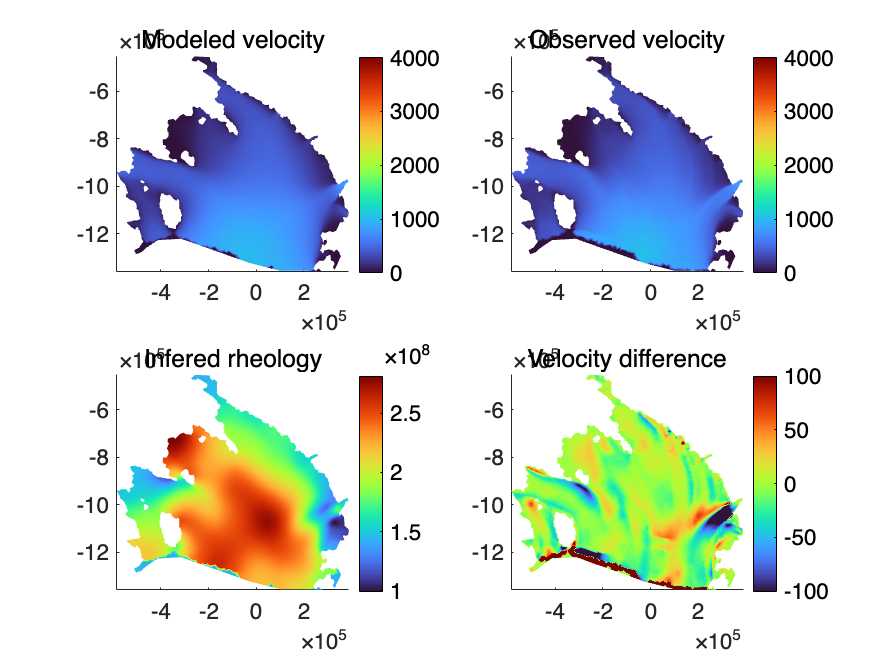

% Plot the results of the inversion

plotmodel(mds,...
'data',mds.results.StressbalanceSolution.Vel,'title','Modeled velocity','colormap','turbo',...
'data',mds.inversion.vel_obs,'title','Observed velocity','colormap','turbo',...
'data',mds.results.StressbalanceSolution.MaterialsRheologyBbar,'title','Infered rheology',...
'data',mds.results.StressbalanceSolution.Vel-mds.inversion.vel_obs,'title','Velocity difference',...
'caxis#1',[0 4000],'caxis#2',[0 4000],'caxis#4',[-100 100])

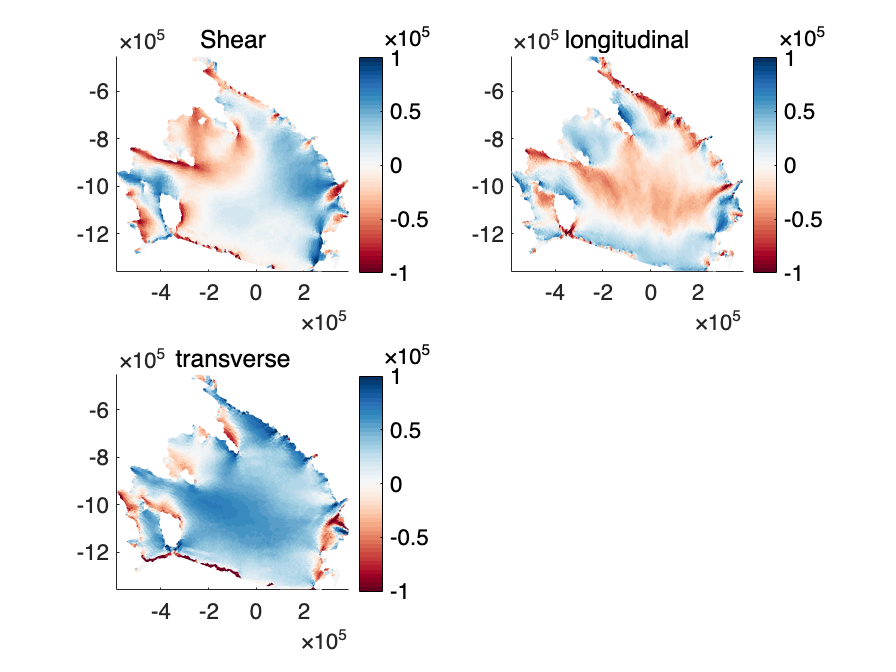

%Get velocities from solutions
vx = mds.results.StressbalanceSolution.Vx;
vy = mds.results.StressbalanceSolution.Vy;
vel = mds.results.StressbalanceSolution.Vel;
mds = mechanicalproperties(mds, vx, vy); % will get the output in mds.results
mds.results.deviatoricstress;

% plotting the Deviatoric Stresses
plotmodel(mds,'data',mds.results.deviatoricstress.xy,'title','Shear',...
'data',mds.results.deviatoricstress.xx,'title','longitudinal',...
'data',mds.results.deviatoricstress.yy,'title','transverse','caxis#all',[-1e5 1e5]);
colormap(brewermap(50, 'RdBu'));

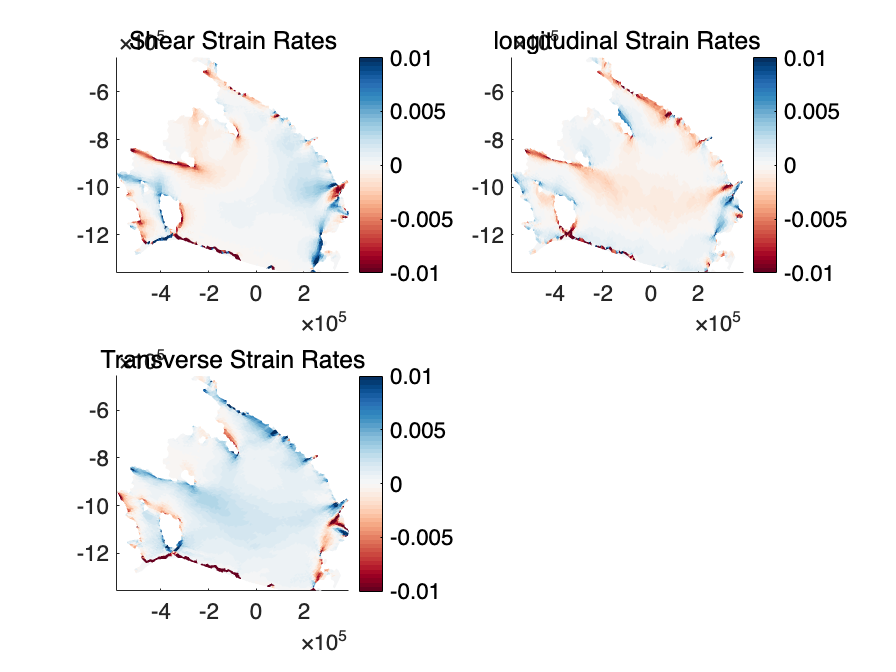

% plotting the Strain Rates
plotmodel(mds,'data',mds.results.strainrate.xy,'title','Shear Strain Rates',...
'data',mds.results.strainrate.xx,'title','longitudinal Strain Rates',...
'data',mds.results.strainrate.yy,'title','Transverse Strain Rates',...
'caxis#all',[-0.01 0.01]);
colormap(brewermap(50, 'RdBu'));

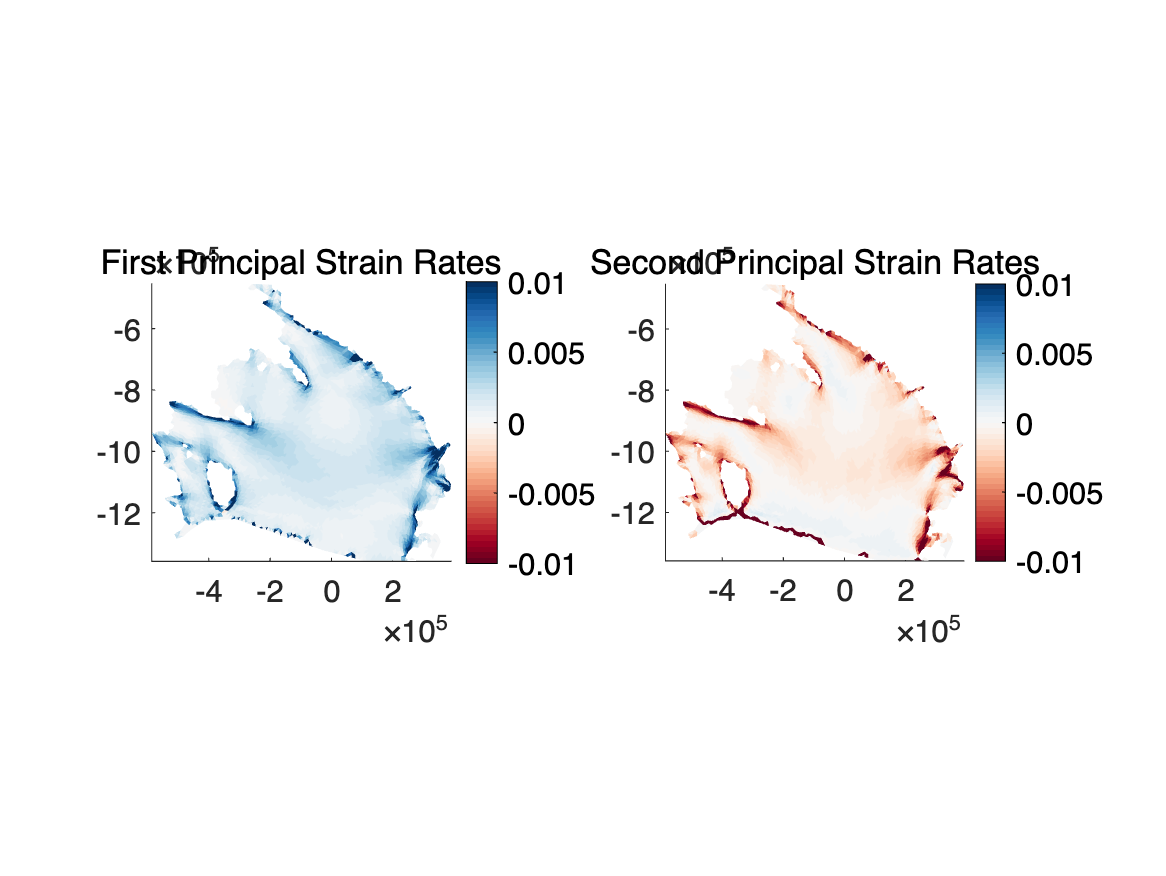

% plotting the Pricnipal Strain Rates
plotmodel(mds,'data',mds.results.strainrate.principalvalue1,'title','First Principal Strain Rates','caxis#1',[-0.01 0.01],...
'data',mds.results.strainrate.principalvalue2,'title','Second Principal Strain Rates','caxis#2',[-0.01 0.01])
colormap(brewermap(50,'RdBu'))

data provided is a struct with the following fields:
   1: nu


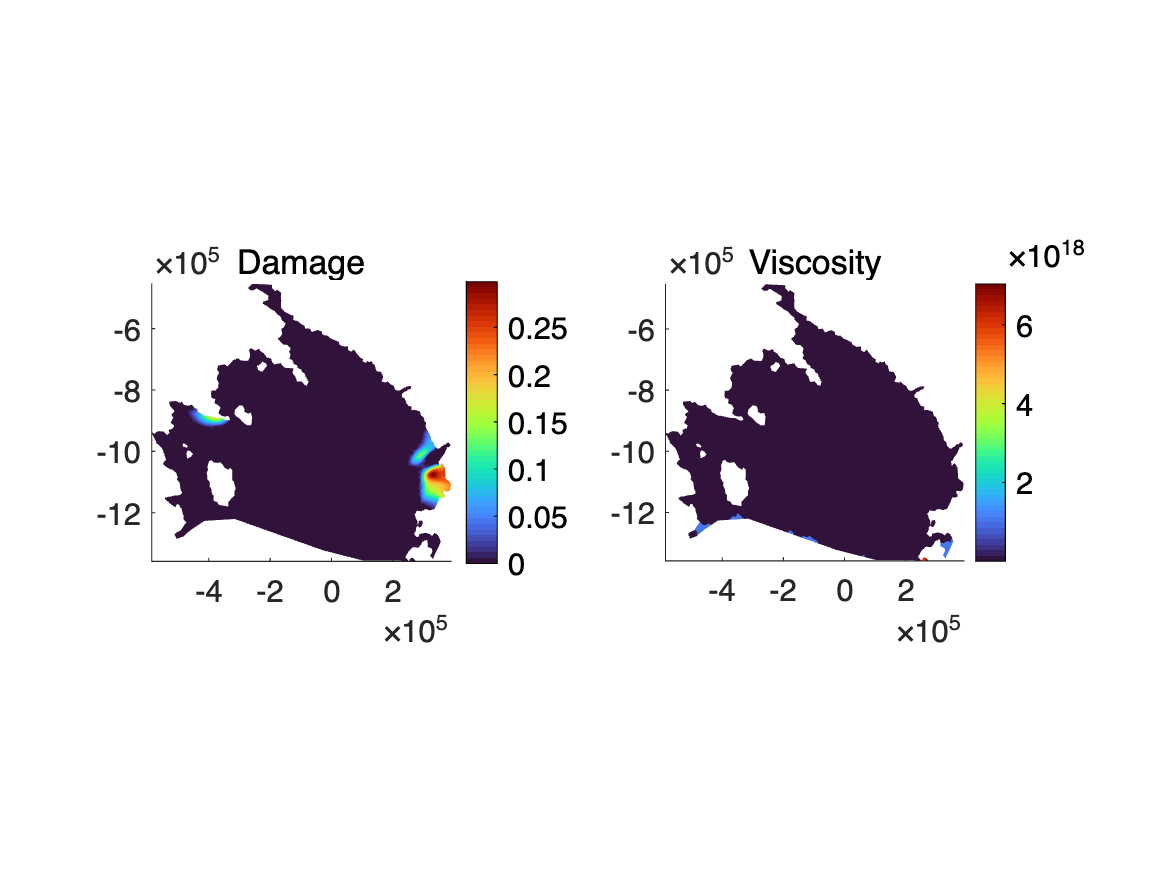

% Estimating Damage parameter from the inversion
mds.results.StressbalanceSolution.D = damagefrominversion(mds);
plotmodel(mds,'data',mds.results.StressbalanceSolution.D,'title','Damage',...
    'data',mds.results.viscosity,'title','Viscosity');

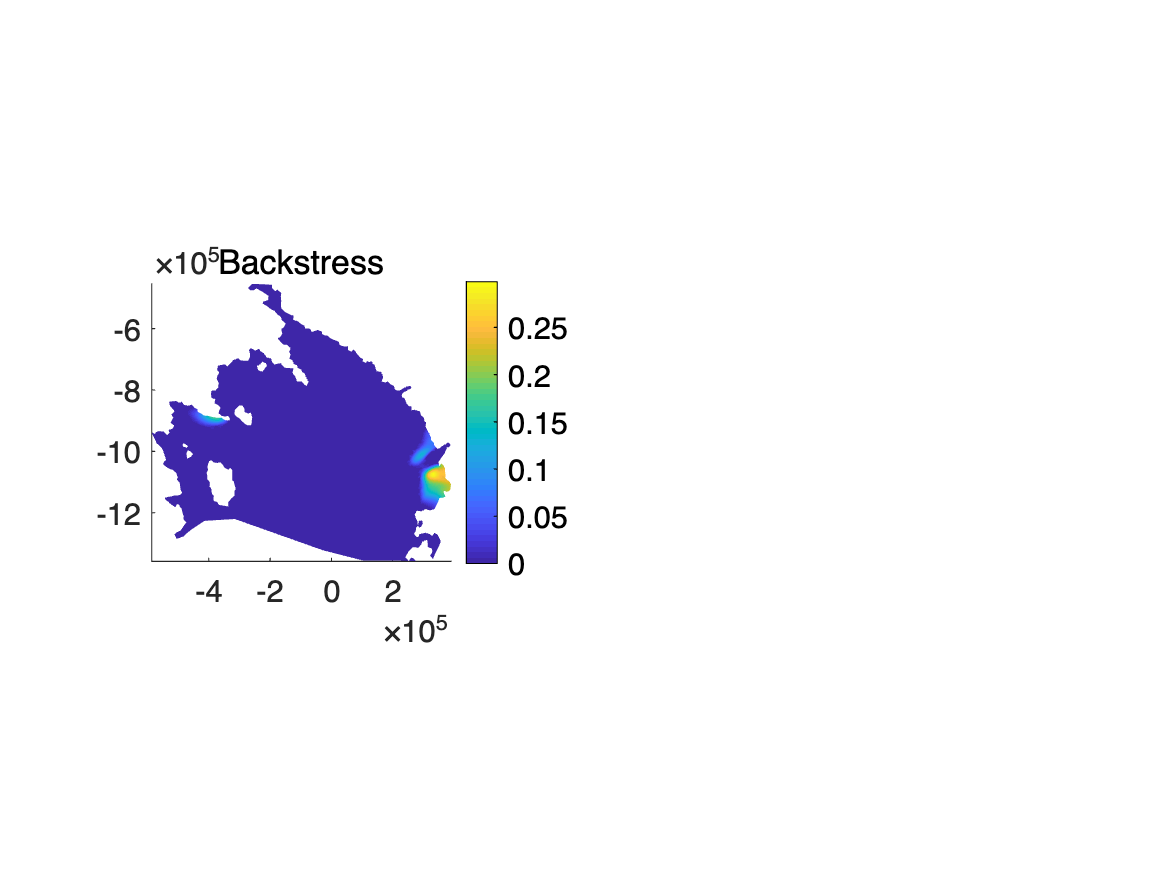

% Compute Backstress using Borstad's method
mds.results.StressbalanceSolution.Backstress = backstressfrominversion(mds,'coordsys','principal');
 plotmodel(mds,'data',mds.results.StressbalanceSolution.D,'title','Backstress','colormap','parula');

%find elements that are floating ice
pos_floating = find(min(md.mask.ocean_levelset(md.mesh.elements),[],2)<0 & min(md.mask.ice_levelset(md.mesh.elements),[],2)<0);

%Recover stresses
vx = mds.results.StressbalanceSolution.Vx;
vy = mds.results.StressbalanceSolution.Vy;
vel = mds.results.StressbalanceSolution.Vel;
md = mechanicalproperties(mds, vx, vy);

%Constants
g = md.constants.g;
rho_i = mds.materials.rho_ice;
rho_w = mds.materials.rho_water;

%Element averaged thickness
H = mean(mds.geometry.thickness(md.mesh.elements),2);
depth = mean(mds.geometry.base(md.mesh.elements),2)-mean(md.geometry.bed(mds.mesh.elements),2);
vx = mean(vx(mds.mesh.elements),2);
vy = mean(vy(mds.mesh.elements),2);
vel = mean(vel(mds.mesh.elements),2);

%Allocate Kn
Kn = NaN(length(mds.mesh.elements),1);
buttress = NaN(mds.mesh.numberofelements,1);

for el=pos_floating'

	%Build stress tensor
    tau_xx = mds.results.deviatoricstress.xx(el);
    tau_yy = mds.results.deviatoricstress.yy(el);
    tau_xy = mds.results.deviatoricstress.xy(el);
    R = [2*tau_xx+tau_yy   tau_xy;tau_xy   2*tau_yy+tau_xx];

	%Decide on outward pointing unit vector
	if 0 %"Flow buttressing" - the supplement
		vector = [vx(el); vy(el)];
	else %"Max buttressing" - the main text
		vector = md.results.deviatoricstress.principalaxis2(el,:)';
	end
	n = vector./sqrt(vector(1)^2+vector(2)^2);

	%Buildsigma_nn and then Kn
	N = n'*R*n;
    N0 = 0.5*g*rho_i.*(1-rho_i./rho_w).*H(el);
	Kn(el) = 1 - N/N0;    % Furst Buttressing Number
    Backstress_Furst(el) = N0 - N; % Estimated Backstress (Pa)
end

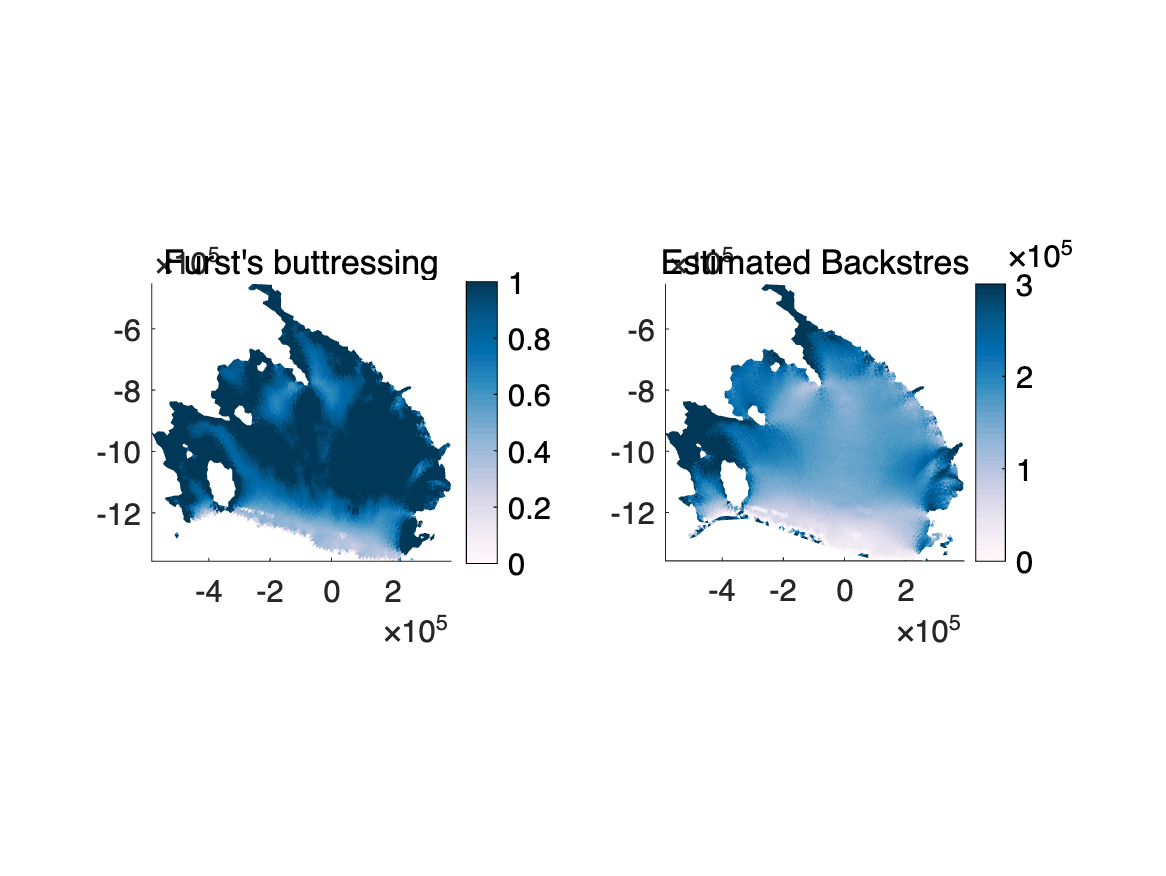

plotmodel(mds,'data',Kn,'title', 'Furst''s buttressing','caxis#1',[0 1], ...
              'data',Backstress_Furst,'title', 'Estimated Backstres','caxis#2',[0 3e5]); 
colormap(brewermap(50,'PuBu'))

save ./Models/Ross_Inversion_Bedmachine mds;